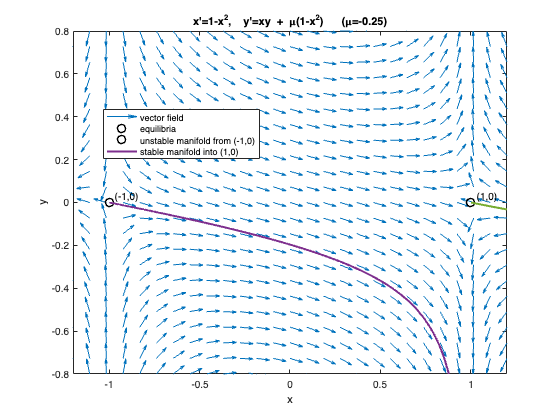

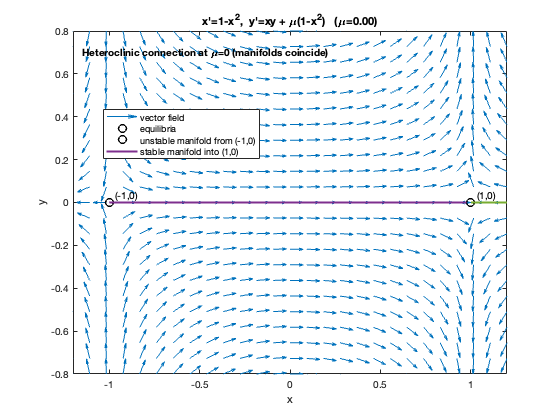

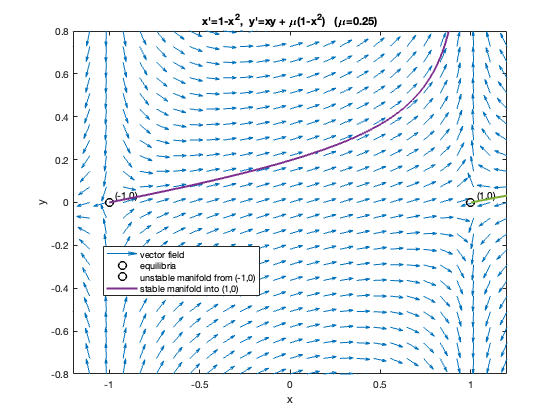

% ex6_heteroclinic_bifurcation_2D.m
% A simple 2D example of a heteroclinic (saddle-connection) bifurcation.
%
% System (parameter mu):
%   x' = 1 - x^2
%   y' = x*y + mu*(1 - x^2)
%
% Equilibria for all mu: (-1,0) and (1,0).
%   - At (-1,0): eigenvalues {+2, -1}  => saddle.
%   - At ( 1,0): eigenvalues {-2, +1}  => saddle.
%
% For mu = 0:
%   y=0 is invariant, and the x-axis segment connects (-1,0) -> (1,0),
%   giving a heteroclinic connection (saddle-to-saddle).
%
% For mu != 0:
%   the connection breaks (manifolds split). This is a classic heteroclinic bifurcation.
%
% This script:
%   (1) Plots phase portraits for mu < 0, mu = 0, mu > 0.
%   (2) Approximates stable/unstable manifolds by integrating from eigenvector directions.
%   (3) Measures a "splitting distance" at the section x=0 as a function of mu.
%
% No toolboxes required.

clear; close all; clc;

mu_list = [-0.25, 0.0, 0.25];
opts = odeset('RelTol',1e-9,'AbsTol',1e-11,'MaxStep',0.05);

%% (A) Phase portraits for representative mu values
for k = 1:numel(mu_list)
    mu = mu_list(k);
    plotPortrait(mu, opts);
end

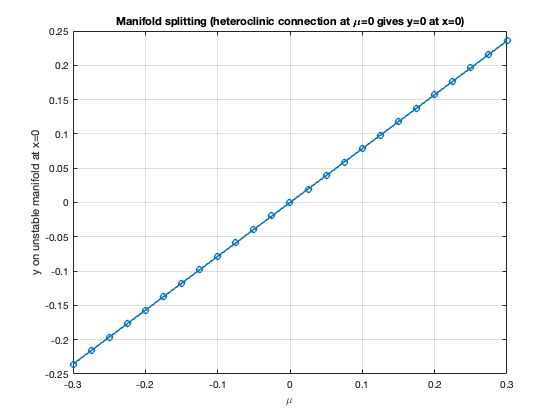


% [Insert figure on slides: Compare mu<0, mu=0, mu>0 showing manifold splitting and the heteroclinic connection at mu=0.]

%% (B) Splitting distance at the section x=0
mu_scan = linspace(-0.3, 0.3, 25);
splitY = nan(size(mu_scan));

for k = 1:numel(mu_scan)
    mu = mu_scan(k);
    splitY(k) = manifoldCrossingAtX0(mu, opts);
end

figure('Name','Heteroclinic splitting distance');
plot(mu_scan, splitY, 'o-', 'LineWidth', 1.5);
xlabel('\mu'); ylabel('y on unstable manifold at x=0');
title('Manifold splitting (heteroclinic connection at \mu=0 gives y=0 at x=0)');
grid on;


%% ---------------- Local functions ----------------


function dz = f(~, z, mu)
    x = z(1); y = z(2);
    dx = 1 - x^2;
    dy = x*y + mu*(1 - x^2);
    dz = [dx; dy];
end

function plotPortrait(mu, opts)
    xlimv = [-1.2 1.2];
    ylimv = [-0.8 0.8];

    [X,Y] = meshgrid(linspace(xlimv(1),xlimv(2),27), linspace(ylimv(1),ylimv(2),23));
    dX = 1 - X.^2;
    dY = X.*Y + mu*(1 - X.^2);

    spd = sqrt(dX.^2 + dY.^2) + 1e-12;
    dXn = dX./spd; dYn = dY./spd;

    figure('Name',sprintf('Heteroclinic demo: mu=%.2f',mu));
    quiver(X,Y,dXn,dYn,0.65,'LineWidth',0.8); hold on;
    xlabel('x'); ylabel('y');
    title(sprintf('x''=1-x^2,  y''=xy + \\mu(1-x^2)   (\\mu=%.2f)',mu));
    xlim(xlimv); ylim(ylimv);

    % Mark equilibria
    plot(-1,0,'ko','MarkerSize',8,'LineWidth',1.5);
    plot( 1,0,'ko','MarkerSize',8,'LineWidth',1.5);
    text(-1,0,'  (-1,0)','VerticalAlignment','bottom');
    text( 1,0,'  (1,0)','VerticalAlignment','bottom');

    % Approximate unstable manifold of (-1,0)
    zL = [-1; 0];
    Ju = [2, 0; 2*mu, -1]; % Jacobian at (-1,0)
    [V,D] = eig(Ju); %#ok<ASGLU>
    % unstable eigenvalue is +2
    v_un = V(:,abs(diag(D)-2)<1e-6);
    v_un = v_un(:,1) / norm(v_un(:,1));
    eps0 = 1e-3;
    z0_un = zL + eps0*v_un;

    [~,z_un] = ode45(@(t,z) f(t,z,mu), [0 6], z0_un, opts);
    plot(z_un(:,1), z_un(:,2), 'LineWidth', 2.0);

    % Approximate stable manifold of (1,0) by integrating backward in time
    zR = [1; 0];
    Js = [-2, 0; -2*mu, 1]; % Jacobian at (1,0)
    [V2,D2] = eig(Js); %#ok<ASGLU>
    % stable eigenvalue is -2
    v_st = V2(:,abs(diag(D2)+2)<1e-6);
    v_st = v_st(:,1) / norm(v_st(:,1));
    z0_st = zR + eps0*v_st;

    [~,z_st] = ode45(@(t,z) f(t,z,mu), [0 -6], z0_st, opts); % backward time
    plot(z_st(:,1), z_st(:,2), 'LineWidth', 2.0);

    legend({'vector field','equilibria','unstable manifold from (-1,0)','stable manifold into (1,0)'}, ...
        'Location','best');

    if abs(mu) < 1e-12
        text(xlimv(1)+0.05, ylimv(2)-0.1, 'Heteroclinic connection at \mu=0 (manifolds coincide)', ...
            'FontWeight','bold');
    end
end

function y_cross = manifoldCrossingAtX0(mu, opts)
    % Integrate unstable manifold of (-1,0) forward and record y where it crosses x=0.
    % If it fails to cross, return NaN.
    zL = [-1; 0];
    Ju = [2, 0; 2*mu, -1];
    [V,D] = eig(Ju);
    v_un = V(:,abs(diag(D)-2)<1e-6);
    v_un = v_un(:,1) / norm(v_un(:,1));
    eps0 = 1e-6;
    z0 = zL + eps0*v_un;

    opts_ev = odeset(opts, 'Events', @(t,z) eventX0(t,z));
    [~,~,te,ze] = ode45(@(t,z) f(t,z,mu), [0 10], z0, opts_ev);
    if isempty(te)
        y_cross = nan;
    else
        y_cross = ze(end,2);
    end
end

function [value, isterminal, direction] = eventX0(~, z)
    value = z(1);       % x = 0 section
    isterminal = 1;     % stop at first crossing
    direction = +1;     % x increasing from negative to positive
end
